clear all
syms r zeta wn omega F0 m t
zeta=sym('zeta','real')

$$zeta = \zeta$$

zeta=sym('zeta','positive')

$$zeta = \zeta$$

wn=sym('wn','real')

$$wn = \mathrm{wn}$$

wn=sym('wn','positive')

$$wn = \mathrm{wn}$$

omega=sym('omega','real')

$$omega = \omega$$

omega=sym('omega','positive')

$$omega = \omega$$

F0=sym('F0','real')

$$F0 = F_{0}$$

F0=sym('F0','positive')

$$F0 = F_{0}$$

m=sym('m','real')

$$m = m$$

m=sym('m','positive')

$$m = m$$

t=sym('t','real')

$$t = t$$

p(r)=r^2+2*zeta*wn*r+wn^2

$$p(r) = r^{2}+2\,\zeta \,r\,\mathrm{wn}+{\mathrm{wn}}^{2}$$

zpsol=(F0/m)*exp(i*omega*t)/p(i*omega)

$$zpsol = \frac{F_{0}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}}{m\,\left(-\omega^{2}+2\,\mathrm{i}\,\zeta \,\omega \,\mathrm{wn}+{\mathrm{wn}}^{2}\right)}$$

gabs=simplify(abs(zpsol))

$$gabs = \frac{F_{0}}{m\,\left|-\omega^{2}+2\,\mathrm{i}\,\zeta \,\omega \,\mathrm{wn}+{\mathrm{wn}}^{2}\right|}$$

c1=imag(zpsol)

$$c1 = -\frac{F_{0}\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}{m\,\left({\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\right)}-\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)}{m\,\left({\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\right)}$$

c2=real(zpsol)

$$c2 = \frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)}{m\,\left({\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\right)}-\frac{F_{0}\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}{m\,\left({\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\right)}$$

g=(sqrt(c1^2+c2^2))

$$g = \begin{array}{l} \sqrt{{\left(\frac{F_{0}\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}{\sigma_{1}}-\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)}{\sigma_{1}}\right)}^{2}+{\left(\frac{F_{0}\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}{\sigma_{1}}+\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)}{\sigma_{1}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=m\,\left({\left(\omega^{2}-{\mathrm{wn}}^{2}\right)}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\right) \end{array}$$

gain=simplify(g)

$$gain = \frac{F_{0}\,\sqrt{\omega^{4}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}-2\,\omega^{2}\,{\mathrm{wn}}^{2}+{\mathrm{wn}}^{4}}}{m\,\left|\omega^{4}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}-2\,\omega^{2}\,{\mathrm{wn}}^{2}+{\mathrm{wn}}^{4}\right|}$$

eq1=diff(g,omega)

$$eq1 = \begin{array}{l} -\frac{2\,\sigma_{2}\,\left(\frac{F_{0}\,t\,\sin\left(\omega \,t\right)\,\sigma_{5}}{m\,\sigma_{4}}-\frac{2\,F_{0}\,\omega \,\cos\left(\omega \,t\right)}{m\,\sigma_{4}}+\frac{2\,F_{0}\,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)}{m\,\sigma_{4}}+\frac{F_{0}\,\cos\left(\omega \,t\right)\,\sigma_{1}\,\sigma_{5}}{m\,{\sigma_{4}}^{2}}+\frac{2\,F_{0}\,\omega \,t\,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)}{m\,\sigma_{4}}-\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)\,\sigma_{1}}{m\,{\sigma_{4}}^{2}}\right)-2\,\sigma_{3}\,\left(\frac{2\,F_{0}\,\omega \,\sin\left(\omega \,t\right)}{m\,\sigma_{4}}-\frac{F_{0}\,\sin\left(\omega \,t\right)\,\sigma_{1}\,\sigma_{5}}{m\,{\sigma_{4}}^{2}}+\frac{F_{0}\,t\,\cos\left(\omega \,t\right)\,\sigma_{5}}{m\,\sigma_{4}}+\frac{2\,F_{0}\,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)}{m\,\sigma_{4}}-\frac{2\,F_{0}\,\omega \,t\,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)}{m\,\sigma_{4}}-\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)\,\sigma_{1}}{m\,{\sigma_{4}}^{2}}\right)}{2\,\sqrt{{\sigma_{2}}^{2}+{\sigma_{3}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=4\,\omega \,\sigma_{5}+8\,\omega \,{\mathrm{wn}}^{2}\,\zeta^{2}\\ \sigma_{2}=\frac{F_{0}\,\cos\left(\omega \,t\right)\,\sigma_{5}}{m\,\sigma_{4}}-\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\sin\left(\omega \,t\right)}{m\,\sigma_{4}}\\ \sigma_{3}=\frac{F_{0}\,\sin\left(\omega \,t\right)\,\sigma_{5}}{m\,\sigma_{4}}+\frac{2\,F_{0}\,\omega \,\mathrm{wn}\,\zeta \,\cos\left(\omega \,t\right)}{m\,\sigma_{4}}\\ \sigma_{4}={\sigma_{5}}^{2}+4\,\omega^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}\\ \sigma_{5}=\omega^{2}-{\mathrm{wn}}^{2} \end{array}$$

sol = solve(eq1,omega)

$$sol = \mathrm{wn}\,\sqrt{1-2\,\zeta^{2}}$$

## Problem 2

fprintf('Problem 2')

Problem 2

clear all
syms r omega t F0
omega=sym('omega','real')

$$omega = \omega$$

omega=sym('omega','positive')

$$omega = \omega$$

t=sym('t','real')

$$t = t$$


% x'' + 3x' + 4x = 4 sin ωt
F0=4

F0 = 4

p(r)=1*r^2+3*r+4

$$p(r) = r^{2}+3\,r+4$$

zpsol=F0*exp(i*omega*t)/p(i*omega)

$$zpsol = \frac{4\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}}{-\omega^{2}+3\,\omega \,\mathrm{i}+4}$$

gabs=simplify(abs(zpsol))

$$gabs = \frac{4}{\sqrt{{\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2}}}$$

c1=imag(zpsol)

$$c1 = -\frac{4\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{{\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2}}-\frac{12\,\omega \,\cos\left(\omega \,t\right)}{{\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2}}$$

c2=real(zpsol)

$$c2 = \frac{12\,\omega \,\sin\left(\omega \,t\right)}{{\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2}}-\frac{4\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{{\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2}}$$


g=(sqrt(c1^2+c2^2))

$$g = \begin{array}{l} 4\,\sqrt{\frac{{\left(\frac{12\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{1}}-\frac{4\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{1}}\right)}^{2}}{16}+\frac{{\left(\frac{4\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{1}}+\frac{12\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{1}}\right)}^{2}}{16}}\\ \mathrm{where}\\ \sigma_{1}={\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2} \end{array}$$

gain=simplify(g)

$$gain = \frac{4}{\sqrt{\omega^{4}+\omega^{2}+16}}$$


eq1=diff(g,omega)

$$eq1 = \begin{array}{l} \frac{2\,\left(\frac{\sigma_{2}\,\left(\frac{12\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{8\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}-\frac{12\,\omega \,\sin\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{4\,t\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{4}}+\frac{12\,\omega \,t\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{4\,\cos\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-4\right)}{{\sigma_{4}}^{2}}\right)}{8}+\frac{\sigma_{3}\,\left(\frac{12\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{8\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{12\,\omega \,\cos\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{4\,t\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{4}}-\frac{12\,\omega \,t\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{4\,\sin\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-4\right)}{{\sigma_{4}}^{2}}\right)}{8}\right)}{\sqrt{\frac{{\sigma_{2}}^{2}}{16}+\frac{{\sigma_{3}}^{2}}{16}}}\\ \mathrm{where}\\ \sigma_{1}=18\,\omega +4\,\omega \,\left(\omega^{2}-4\right)\\ \sigma_{2}=\frac{12\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{4\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{4\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-4\right)}{\sigma_{4}}+\frac{12\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}\\ \sigma_{4}={\left(\omega^{2}-4\right)}^{2}+9\,\omega^{2} \end{array}$$

solve(eq1,omega)

 
ans =
 
Empty sym: 0-by-1
 



m = 1

m = 1

b = 3

b = 3

k = 4

k = 4

wres = sqrt(k/m-2*(b/(2*m))^2)

wres = 0.0000 + 0.7071i

fprintf("The gain frequency is %s and the resonance frequency is %4.4f%+4.4fi.",gain,real(wres),imag(wres))

The gain frequency is 4/(omega^2 + omega^4 + 16)^(1/2) and the resonance frequency is 0.0000+0.7071i.

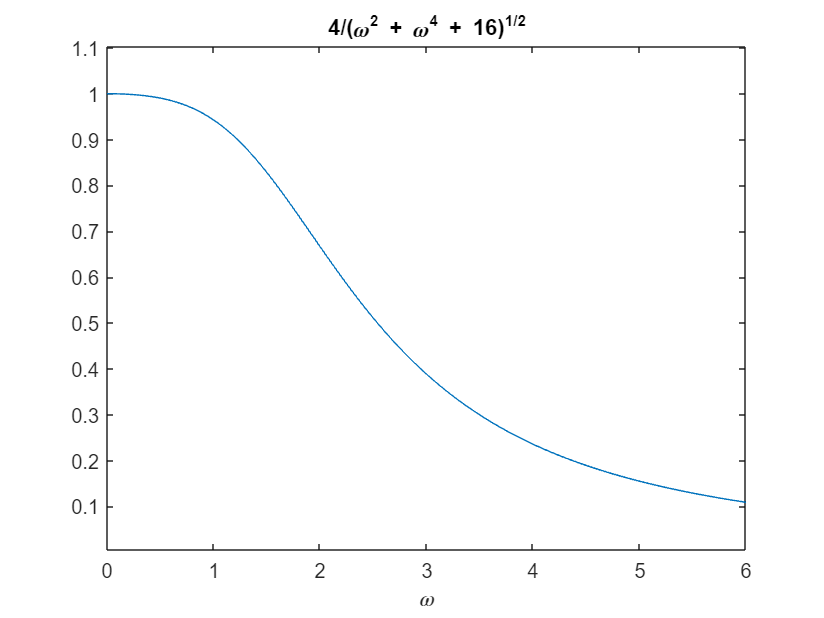


ezplot(gain,[0,6])

## Problem 4

fprintf('Problem 4')

Problem 4

clear all
syms r omega t F0
omega=sym('omega','real')

$$omega = \omega$$

omega=sym('omega','positive')

$$omega = \omega$$

t=sym('t','real')

$$t = t$$


% x'' + 6x' + 25x = 3 sin ωt
F0=3

F0 = 3

p(r)=1*r^2+6*r+25

$$p(r) = r^{2}+6\,r+25$$

zpsol=F0*exp(i*omega*t)/p(i*omega)

$$zpsol = \frac{3\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}}{-\omega^{2}+6\,\omega \,\mathrm{i}+25}$$

gabs=simplify(abs(zpsol))

$$gabs = \frac{3}{\sqrt{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}}$$

c1=imag(zpsol)

$$c1 = -\frac{3\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}-\frac{18\,\omega \,\cos\left(\omega \,t\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}$$

c2=real(zpsol)

$$c2 = \frac{18\,\omega \,\sin\left(\omega \,t\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}-\frac{3\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{{\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2}}$$


g=(sqrt(c1^2+c2^2))

$$g = \begin{array}{l} 3\,\sqrt{\frac{{\left(\frac{18\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{1}}-\frac{3\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{1}}\right)}^{2}}{9}+\frac{{\left(\frac{3\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{1}}+\frac{18\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{1}}\right)}^{2}}{9}}\\ \mathrm{where}\\ \sigma_{1}={\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2} \end{array}$$

gain=simplify(g)

$$gain = \frac{3}{\sqrt{\omega^{4}-14\,\omega^{2}+625}}$$


eq1=diff(g,omega)

$$eq1 = \begin{array}{l} \frac{3\,\left(\frac{2\,\sigma_{2}\,\left(\frac{18\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{6\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}-\frac{18\,\omega \,\sin\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{3\,t\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}+\frac{18\,\omega \,t\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{3\,\cos\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-25\right)}{{\sigma_{4}}^{2}}\right)}{9}+\frac{2\,\sigma_{3}\,\left(\frac{18\,\cos\left(\omega \,t\right)}{\sigma_{4}}+\frac{6\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{18\,\omega \,\cos\left(\omega \,t\right)\,\sigma_{1}}{{\sigma_{4}}^{2}}+\frac{3\,t\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}-\frac{18\,\omega \,t\,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{3\,\sin\left(\omega \,t\right)\,\sigma_{1}\,\left(\omega^{2}-25\right)}{{\sigma_{4}}^{2}}\right)}{9}\right)}{2\,\sqrt{\frac{{\sigma_{2}}^{2}}{9}+\frac{{\sigma_{3}}^{2}}{9}}}\\ \mathrm{where}\\ \sigma_{1}=72\,\omega +4\,\omega \,\left(\omega^{2}-25\right)\\ \sigma_{2}=\frac{18\,\omega \,\sin\left(\omega \,t\right)}{\sigma_{4}}-\frac{3\,\cos\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}\\ \sigma_{3}=\frac{3\,\sin\left(\omega \,t\right)\,\left(\omega^{2}-25\right)}{\sigma_{4}}+\frac{18\,\omega \,\cos\left(\omega \,t\right)}{\sigma_{4}}\\ \sigma_{4}={\left(\omega^{2}-25\right)}^{2}+36\,\omega^{2} \end{array}$$

solve(eq1,omega)

$$ans = \sqrt{7}$$


m = 1

m = 1

b = 6

b = 6

k = 25

k = 25

wres = sqrt(k/m-2*(b/(2*m))^2)

wres = 2.6458

fprintf("The gain frequency is %s and the resonance frequency is %4.4f%+4.4fi.",gain,real(wres),imag(wres))

The gain frequency is 3/(omega^4 - 14*omega^2 + 625)^(1/2) and the resonance frequency is 2.6458+0.0000i.

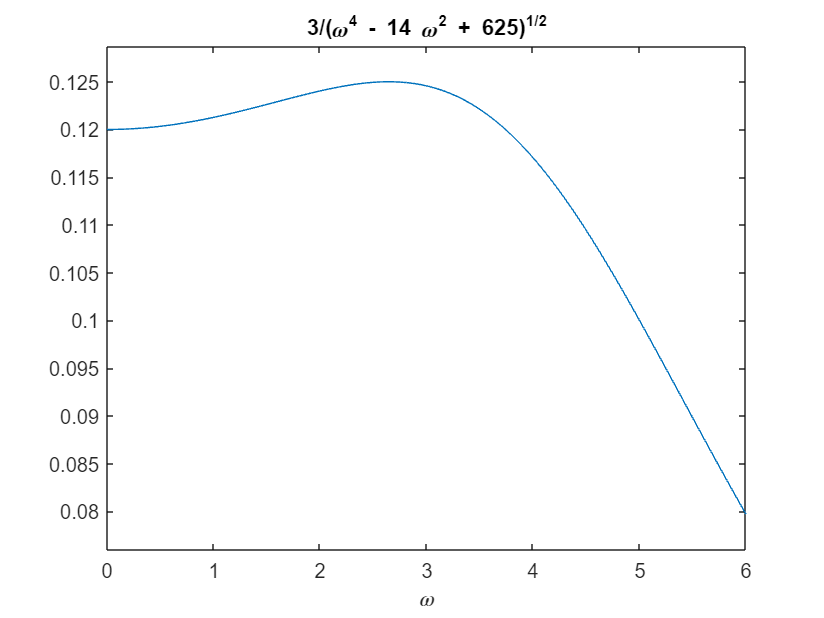


ezplot(gain,[0,6])